# 3次元空間での座標変換

## 座標変換する3次元オブジェクトの作成

clear; close all;

Lx = 0.1;
Ly = 0.2;
Lz = 0.3;

origin = [0, 0, 0];

object0_vertices = [
    origin(1), origin(2), origin(3);
    origin(1)+Lx, origin(2), origin(3);
    origin(1), origin(2)+Ly, origin(3);
    origin(1), origin(2), origin(3)+Lz;
    origin(1)+Lx, origin(2)+Ly, origin(3);
    origin(1), origin(2)+Ly, origin(3)+Lz;
    origin(1)+Lx,  origin(2), origin(3)+Lz;
    origin(1)+Lx, origin(2)+Ly, origin(3)+Lz];

object0_faces =  [
    1, 2, 5, 3;  
    1, 3, 6, 4;  
    1, 4, 7, 2;  
    4, 7, 8, 6;  
    2, 5, 8, 7;  
    3, 6, 8, 5]; 


figure;
object0 = patch('Faces', object0_faces, 'Vertices', object0_vertices,'FaceColor', 'b');

xlabel('x'); ylabel('y'); zlabel('z');
axis vis3d equal;
view([-37.5, 30]);
xlim([-0.7, 0.7]);
ylim([-0.7, 0.7]);
zlim([-0.7,0.7]);
camlight;
grid on;
hold on;

## 作成した3次元オブジェクトを座標変換

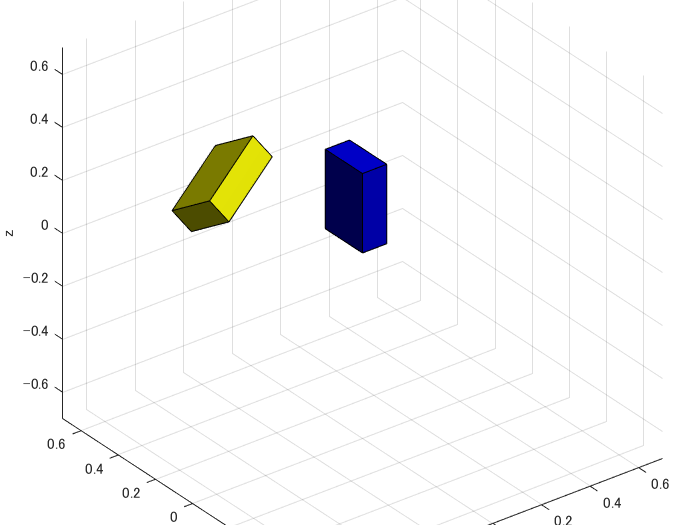

move_position = [-0.4, 0.3, 0.2];
move_rotation_XYZ = [-pi/4; pi/3; pi/12];

x_axis_R = [
    1, 0, 0;
    0, cos(move_rotation_XYZ(1)), -sin(move_rotation_XYZ(1));
    0, sin(move_rotation_XYZ(1)), cos(move_rotation_XYZ(1))];

y_axis_R = [
    cos(move_rotation_XYZ(2)), 0, sin(move_rotation_XYZ(2));
    0, 1, 0;
    -sin(move_rotation_XYZ(2)), 0, cos(move_rotation_XYZ(2))];

z_axis_R = [
    cos(move_rotation_XYZ(3)), -sin(move_rotation_XYZ(3)), 0;
    sin(move_rotation_XYZ(3)), cos(move_rotation_XYZ(3)), 0;
    0, 0, 1];

xyz_R = x_axis_R*y_axis_R*z_axis_R;

object1_vertices = move_position + object0_vertices*xyz_R';
object1_faces = object0_faces;

object1 = patch('Faces', object1_faces, 'Vertices', object1_vertices,'FaceColor', 'y');